# 02. 홀 센서에서 측정한 인터럽트의 동작 횟수를 바탕으로 시간에 따른 선풍기의 RPM을 계산하여 그래프로 나타내고 분석하시오.

# 1. Data Loading

% 각 데이터는 0.5초당 interrupt 동작 횟수

data_with_zero = importdata('첨부파일2_hall센서.txt')    % 0값을 포함한 원래의 data

data_with_zero =      0
     0
     7
     7
     7
     7
     7
     7
     6
     5


data_without_zero = data_with_zero(data_with_zero~=0) % 0값을 제외한 data

data_without_zero =      7
     7
     7
     7
     7
     7
     6
     5
     7
     8


# 2. 0.5초마다 interrupt가 발생한 평균 횟수를 구한다.

interrupt_mean_with_zero = mean(data_with_zero);
fprintf("선풍기의 FAN은 평균적으로 0.5초마다 %f바퀴씩 돌았다.", interrupt_mean_with_zero)

선풍기의 FAN은 평균적으로 0.5초마다 5.655172바퀴씩 돌았다.


interrupt_mean_with_zero = mean(data_with_zero);


# 2_1. 0.5초마다 interrupt가 발생한 평균 횟수를 구한다.

# (단, 선풍기가 돌지 않은 시점인 0값의 data는 제외한다)

interrupt_mean_without_zero = mean(data_without_zero);
fprintf("[0값을 제거한]선풍기의 FAN은 평균적으로 0.5초마다 %f바퀴씩 돌았다.", interrupt_mean_without_zero)

[0값을 제거한]선풍기의 FAN은 평균적으로 0.5초마다 6.833333바퀴씩 돌았다.


interrupt_mean_without_zero = mean(data_without_zero);


# 3. Resolutions Per Minute으로 변환하기

RPM_with_zero = (interrupt_mean_with_zero)*2*60

RPM_with_zero = 678.6207

fprintf("선풍기의 FAN의 분당 회전수는 %f [RPM]이다.", RPM_with_zero)

선풍기의 FAN의 분당 회전수는 678.620690 [RPM]이다.

# 3_1. Resolutions Per Minute으로 변환하기

RPM_without_zero = (interrupt_mean_without_zero)*2*60

RPM_without_zero = 820

fprintf("[0값을 제거한]선풍기의 FAN의 분당 회전수는 %f [RPM]이다.", RPM_without_zero)

[0값을 제거한]선풍기의 FAN의 분당 회전수는 820.000000 [RPM]이다.

# 4. Graph로 나타내기

% x축은 0.5초 간격.
% y축은 RPM
t_len = length(data_with_zero);
x = (0:1:t_len-1) * 0.5

x =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000


y = (data_with_zero * 2) * 60

y =      0
     0
   840
   840
   840
   840
   840
   840
   720
   600


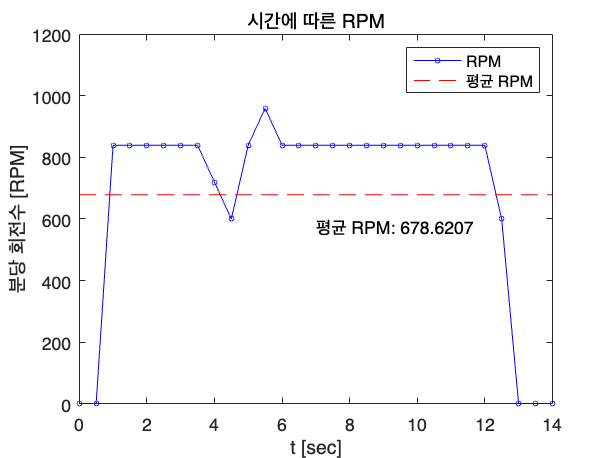

y2 = repmat((interrupt_mean_with_zero)*2*60, 1, t_len);

% 그래프 그리기
plot(x, y, 'bo-', x, y2, 'r--', 'MarkerSize', 3);
legend('RPM', '평균 RPM'); 
text(7, RPM_with_zero-100, ['평균 RPM: ' num2str(RPM_with_zero)]);      
xlabel('t [sec]');           
ylabel('분당 회전수 [RPM]');    
ylim([0 1200])
title('시간에 따른 RPM');  

# 4.1 Graph로 나타내기

% x축은 0.5초 간격.
% y축은 RPM

t_len = length(data_without_zero);
x = (0:1:t_len-1) * 0.5

x =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000


y = (data_without_zero * 2) * 60

y =    840
   840
   840
   840
   840
   840
   720
   600
   840
   960


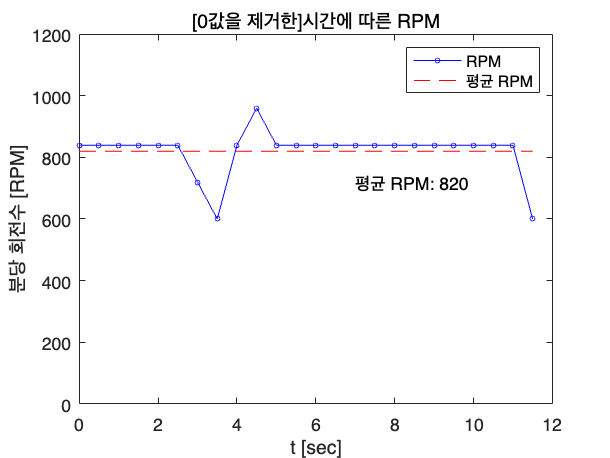

y2 = repmat((interrupt_mean_without_zero)*2*60, 1, t_len);

plot(x, y, 'bo-', x, y2, 'r--', 'MarkerSize', 3);
legend('RPM', '평균 RPM'); 
text(7, RPM_without_zero-100, ['평균 RPM: ' num2str(RPM_without_zero)]);  
xlabel('t [sec]');           
ylabel('분당 회전수 [RPM]');    
ylim([0 1200])
title('[0값을 제거한]시간에 따른 RPM');  